clear all
dataset = readmatrix('Oct.xlsx')

dataset =            1         952         884
           2         932         867
           3         927         856
           4         935         851
           5        1004         871
           6        1157         910
           7        1298         979
           8        1339        1065
           9        1340        1112
          10        1337        1119


FirstYear = dataset(:,1:2);
SecondYear = dataset(:,3);

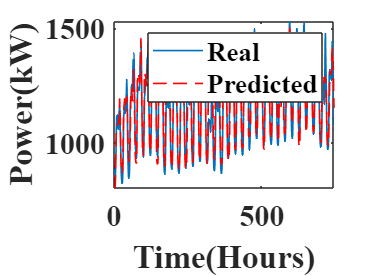

X = FirstYear';
T= SecondYear';
trainFcn = 'trainscg';
hiddenSizes1=30;
net = layrecnet(1:2,hiddenSizes1,trainFcn);
net.divideFcn="";
net.trainparam.epochs=3000;
[net]=train(net,X,T);
y_train=net(X);
plot(T,'LineWidth',1);
hold on;
plot(y_train,'r--','LineWidth',1)
legend('Real','Predicted')
xlabel('Time(Hours)');
ylabel('Power(kW)');
set(gca,'Fontsize',18,'FontWeight','bold','FontName','Times New Roman');
hold off

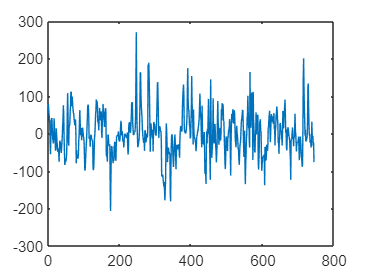

errortrain=T-y_train;
plot(errortrain)

RMSE = sqrt(mean((T-y_train).^2))

RMSE = 56.7439

MSE = mse(net,T,y_train)

MSE = 3.2199e+03

MAE = mae(errortrain)

MAE = 42.3753

MAPE = mean((abs(y_train-T))./T)

MAPE = 0.0359

S=std(errortrain)

S = 56.7820